# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### **Dot Product**  

Many techniques for extracting frequency information from a time-domain signal rely on a mathematical procedure called *convolution*, which in turn relies on a procedure called the *dot product*.  

Dot product: It can be thought of as a sum of elements in one vector weighted by elements of another vector (a signal-processing interpretation). a single number that is computed based on two vectors of equal length.

% Lets Practice
a = randn(10,1);
b = randn(10,1);
dot = zeros(size(a));
for i = 1:length(a)
    dot(i) = a(i) * b(i)
end

dot =     0.5966
         0
         0
         0
         0
         0
         0
         0
         0
         0


dot =     0.5966
    1.3851
         0
         0
         0
         0
         0
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
         0
         0
         0
         0
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
         0
         0
         0
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
         0
         0
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
    1.4883
         0
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
    1.4883
    0.2364
         0
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
    1.4883
    0.2364
    0.2291
         0
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
    1.4883
    0.2364
    0.2291
    0.4027
         0


dot =     0.5966
    1.3851
   -0.7666
   -1.3197
   -1.4394
    1.4883
    0.2364
    0.2291
    0.4027
    1.3474


dot_pro = sum(dot)

dot_pro = 2.1597


dot_pro2 = sum(a.*b)

dot_pro2 = 2.1597

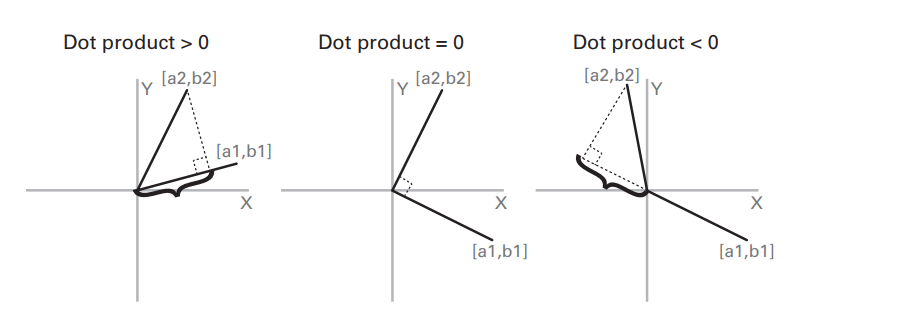

### Convolution

Convolution can have several interpretations: you can think of convolution as a time series of one signal weighted by another signal that slides along the first signal (a signal-processing interpretation). convolution is performed by computing the dot product between two vectors, shifting one vector in time relative to the other vector, computing the dot product again, and so on.  

*In convolution, one vector is considered the signal, and the other vector is considered the kernel.  *

*Convolution entails sliding the kernel along the data and obtaining a result that shows what features the signal and the kernel have in common.   *

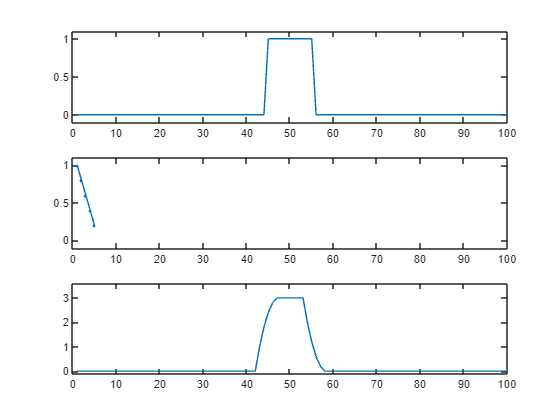

% impulse function (all zeros; 1 in the middle)
impfun = zeros(1,100);
impfun(45:55)=1;

kernel = [1 .8 .6 .4 .2]; 

% matlab's convolution function
matlab_conv_result = conv(impfun,kernel,'same');

figure
% plot the signal (impulse or boxcar)
subplot(311)
plot(impfun)
set(gca,'ylim',[-.1 1.1])

% plot the kernel
subplot(312)
plot(kernel,'.-')
set(gca,'xlim',[0 100],'ylim',[-.1 1.1])

% plot the result of convolution
subplot(313)
plot(matlab_conv_result)
set(gca,'xlim',[0 100],'ylim',[-.1 3.6])

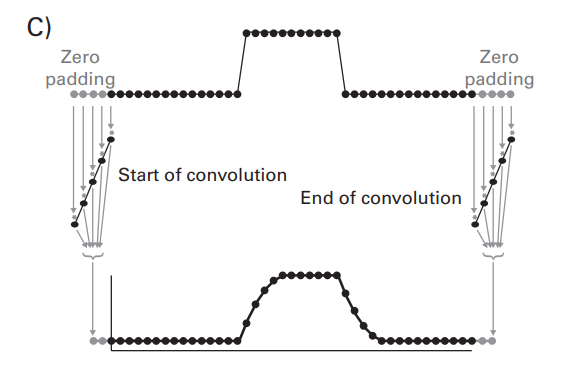

convolution actually begins with the kernel aligned to the left such that the rightmost point of the kernel (after it is reversed) overlaps with the leftmost point of the data (10.3C). Because the two vectors must have the same number of points in order to compute a dot product, zeros are added before the start of the signal. The number of zeros added is the length of the kernel minus one (because the rightmost point of the kernel overlaps with the first point of the signal). These extra zeros do not contribute to the result because zero times a kernel is zero. Then, convolution runs each step toward the right, and it stops when the leftmost point of the kernel is aligned with the rightmost point of the signal. Again, zeros are added after the end of the signal to be able to perform a dot product.

The formula for how long the result of the convolution will be is length(signal) + length(kernel) – 1.

###   **Convolution versus Cross-Covariance**

Convolution and cross-covariance (or cross-correlation; the cross-correlation is simply the cross-covariance scaled by the variances) are similar in concept but slightly different in algorithm. Both are methods to compute the time-varying mapping between vectors, but with convolution the kernel is reversed, whereas with cross-covariance the kernel is kept in its original orientation. If the convolution kernel is temporally symmetric—and thus is the same whether flipped backward or not — convolution and cross-covariance yield identical results.

### **The Purpose of Convolution for EEG Data Analyses**    

In EEG data analyses, convolution is used to** isolate frequency-band-specific activity **and to **localize that frequency-band-specific activity in time.** 

This is ***done by convolving wavelets***— ***time-limited sine waves***—with EEG data. As the wavelet (the convolution kernel) is dragged along the EEG data (the convolution signal),** it reveals when and to what extent the EEG data contain features that look like the wavelet. **When convolution is repeated on the same EEG data using wavelets of different frequencies, a time-frequency representation can be formed.

### **Making Waves**

### 

*A *is the amplitude of the sine wave, π is pi, or 3.141 . . . , *f *is the frequency of the sine wave, *t *is time (this could also be space, but only time-varying sine waves are discussed here), and *θ *is the phase angle offset.

% Lets Practice
srate = 250;
t = 1:1/srate:10;
A = 1;
F = 10;
phase = pi/4;
x = A*sin(2*pi*F*t + phase)

x =     0.7071    0.8607    0.9603    0.9995    0.9759    0.8910    0.7501    0.5621    0.3387    0.0941   -0.1564   -0.3971   -0.6129   -0.7902   -0.9178   -0.9877   -0.9956   -0.9409   -0.8271   -0.6613   -0.4540   -0.2181    0.0314    0.2790    0.5090    0.7071    0.8607    0.9603    0.9995    0.9759    0.8910    0.7501    0.5621    0.3387    0.0941   -0.1564   -0.3971   -0.6129   -0.7902   -0.9178   -0.9877   -0.9956   -0.9409   -0.8271   -0.6613   -0.4540   -0.2181    0.0314    0.2790    0.5090


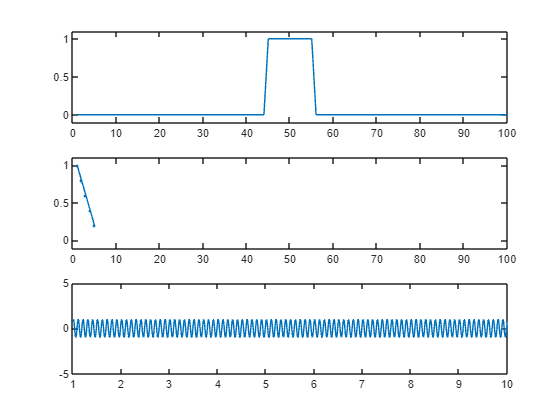

plot(t, x)
set(gca, 'ylim', [-5 5])

 now please increase the frequency. what do you see?

now please increase the amplitude. what do you see?

now please increase the sampling rate. what do you see?

**Now Lets create a mixture of sine waves**

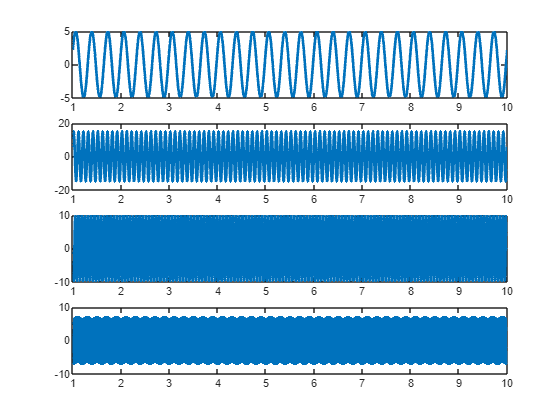

% Lets Practice

f = [3 10 15 35];
A = [5 15 10 7];
P= [pi/7 pi/8 pi -pi/2];
t = 1:1/250:10;
signal = zeros(4, length(t));
for i = 1:length(f)
    subplot(4,1,i)
    signal(i,:) = A(i)*sin(2*pi*f(i)*t + P(i));
    plot(t, signal(i,:), 'linew', 2)
end

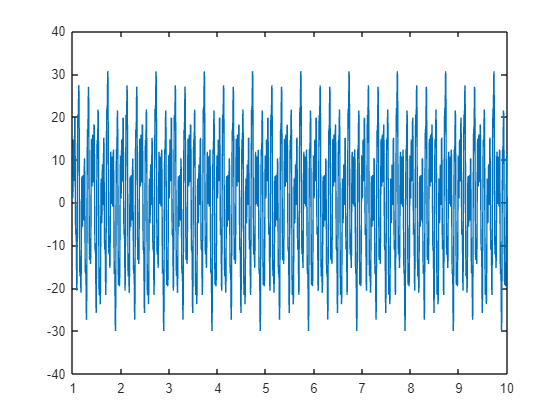


figure;
EEG = sum(signal);
plot(t, EEG)

**Exercises 1**

1. Create two kernels for convolution: one that looks like an inverted U and one that looks

like a decay function. There is no need to be too sophisticated in generating, for example, a

Gaussian and an exponential; numerical approximations are fine.

2. Convolve these two kernels with 50 time points of EEG data from one electrode. Make a

plot showing the kernels, the EEG data, and the result of the convolution between the data

and each kernel. Use time-domain convolution as explained in this chapter and as illustrated

in the online Matlab code. Based on visual inspection, what is the effect of convolving the

EEG data with these two kernels?  

### **The Discrete Time Fourier Transform, the FFT, and the Convolution Theorem**  

It is the computational backbone of most EEG data analyses. In turn, the backbone of the Fourier transform is the dot product.

The idea behind the discrete time Fourier transform is fairly simple: 

- create a sine wave and compute the dot product between that sine wave and the time series data. 

- Then create another sine wave with a different frequency and compute the dot product between that sine wave and the same time series data. 

- The number of sine waves you create, and the frequency of each sine wave, is determined by the ***number of data points in the time series data *** 

N = 10; % length of sequence
data = rand(1,N); % random numbers
% initialize Fourier coefficients
fourier = zeros(size(data));
time = (0:N-1)/N; % time starts at 0; dividing by N normalizes to 1
% Fourier transform
for fi=1:N
% create sine wave
sine_wave = exp(-1i*2*pi*(fi-1).*time);
% compute dot product between sine wave and data
fourier(fi) = sum(sine_wave.*data);
end

**Exercises 2**

Please describe the code above? why we used exp instead of sin? why for each sine_wave we wrote fi -1 instead of fi? (Hint: you can read page 125 of the Cohen Book)

or what this on youtube:

[https://www.youtube.com/watch?v=Kpw7QyVTm6Y](https://www.youtube.com/watch?v=Kpw7QyVTm6Y)

### **How to visualize ?**

Now that you have computed the Fourier transform, how can you view the results? Remember that the Fourier transform provides a 3-D representation of the data in terms of frequency, power, and phase. Very often, the phase information is ignored when results of a Fourier analysis are shown, thus leaving two dimensions to show (the 3-D representation is considered below).   

time=-1:1/srate:1;

% create three sine waves
s1 = sin(2*pi*3*time);
s2 = 0.5*sin(2*pi*8*time);
s3 = s1+s2;

% plot the sine waves
figure
for i=1:3
    subplot(2,3,i)
    
    % plot sine waves, using the eval command (evaluate the string)
    eval([ 'plot(time,s' num2str(i) ')' ]);
    set(gca,'ylim',[-1.6 1.6],'ytick',-1.5:.5:1.5)
    
    % plot power
    subplot(2,3,i+3)
    f  = eval([ 'fft(s' num2str(i) ')/length(time)' ]);
    hz = linspace(0,srate/2,floor(length(time)/2)+1);
    bar(hz,abs(f(1:length(hz))*2))
    set(gca,'xlim',[0 11],'xtick',0:10,'ylim',[0 1.2])
end

*Note: that the phase here refers to the position of the ****sine wave at each frequency when it crosses time = 0****; this is slightly different from the phase angle time series. *  

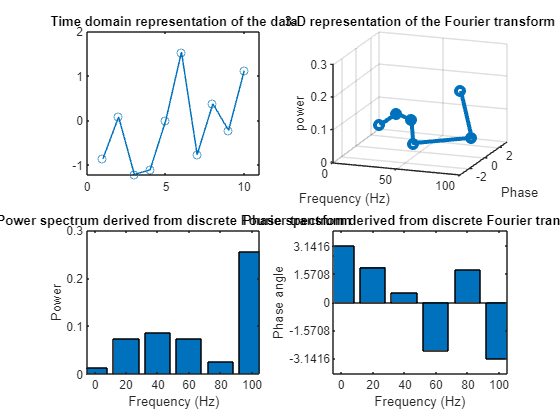


N       = 10;         % length of sequence
data    = randn(1,N); % random numbers
srate   = 200;        % sampling rate in Hz
nyquist = srate/2;    % Nyquist frequency -- the highest frequency you can measure in the data


% initialize Fourier output matrix
fourier = zeros(size(data)); 

% These are the actual frequencies in Hz that will be returned by the
% Fourier transform. The number of unique frequencies we can measure is
% exactly 1/2 of the number of data points in the time series (plus DC). 
frequencies = linspace(0,nyquist,N/2+1);
time = ((1:N)-1)/N;

% Fourier transform is dot-product between sine wave and data at each frequency
for fi=1:N
    sine_wave   = exp(-1i*2*pi*(fi-1).*time);
    fourier(fi) = sum(sine_wave.*data);
end
fourier=fourier/N;


figure
subplot(221)
plot(data,'-o')
set(gca,'xlim',[0 N+1])
title('Time domain representation of the data')

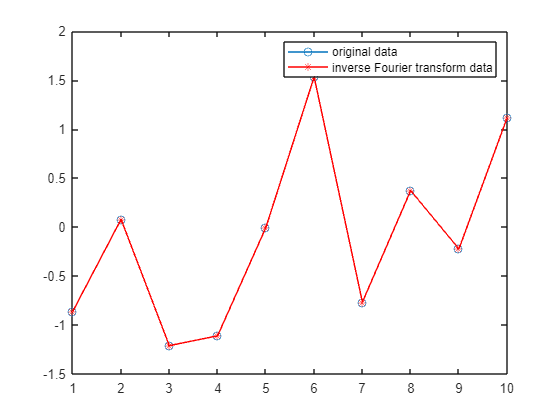


subplot(222)
plot3(frequencies,angle(fourier(1:N/2+1)),abs(fourier(1:N/2+1)).^2,'-o','linew',3)
grid on
xlabel('Frequency (Hz)')
ylabel('Phase')
zlabel('power')
title('3-D representation of the Fourier transform')
view([20 20])

subplot(223)
bar(frequencies,abs(fourier(1:N/2+1)).^2)
set(gca,'xlim',[-5 105])
xlabel('Frequency (Hz)')
ylabel('Power')
title('Power spectrum derived from discrete Fourier transform')

subplot(224)
bar(frequencies,angle(fourier(1:N/2+1)))

set(gca,'xlim',[-5 105])
xlabel('Frequency (Hz)')
ylabel('Phase angle')
set(gca,'ytick',-pi:pi/2:pi)
title('Phase spectrum derived from discrete Fourier transform')

***Note: ***If you inspect the online Matlab code, you may notice that only the first half of the results of the Fourier transform are plotted. The first half of the Fourier series contains the “ positive ” frequencies, and the second half of the Fourier series contains the “ negative ” frequencies. The negative frequencies capture sine waves that travel in reverse order around the complex plane compared to those that travel forward (positive frequencies).  

### **Inverse Fourier Transform**

The Fourier transform allows you to represent a time series in the frequency domain. It is often stated that the Fourier transform is a perfect frequency-domain representation of a time-domain signal. If this is true, it must be possible to reconstruct the original time series data with only the frequency domain information. This is done through the inverse Fourier transform.  

% Compute sine waves and sum to recover the original time series
reconstructed_data = zeros(size(data));
for fi=1:N
    % scale sine wave by fourier coefficient
    sine_wave = fourier(fi)*exp(1i*2*pi*(fi-1).*time);
    % sum sine waves together (take only real part)
    reconstructed_data = reconstructed_data + real(sine_wave);
end

figure
plot(data,'-o')
hold on
plot(reconstructed_data,'r-*')

legend({'original data';'inverse Fourier transform data'})

### The fast Fourier transform (FFT)   

There are several methods for increasing the efficiency of the Fourier transform, including the fast Fourier transform (FFT) that is implemented in Matlab using the function fft. The Matlab function for the inverse Fourier transform is called ifft.   

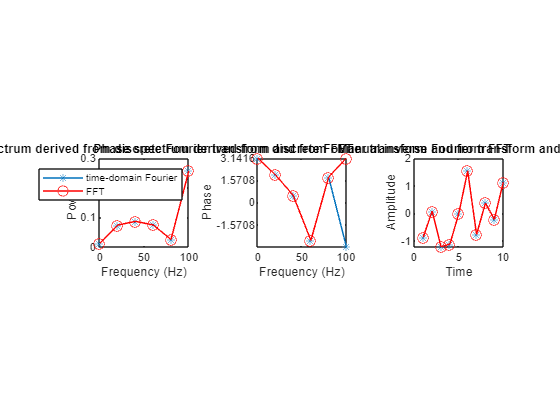

fft_data = fft(data)/N;

figure
subplot(131)
plot(frequencies,abs(fourier(1:N/2+1)).^2,'*-')
hold on
plot(frequencies,abs(fft_data(1:N/2+1)).^2,'ro-','markersize',8)
% make plot look nice
xlabel('Frequency (Hz)')
ylabel('Power')
title('Power spectrum derived from discrete Fourier transform and from FFT')
axis square
legend({'time-domain Fourier';'FFT'})

subplot(132)
plot(frequencies,angle(fourier(1:N/2+1)),'*-')
hold on

plot(frequencies,angle(fft_data(1:N/2+1)),'ro-','markersize',8)
% make plot look nice
xlabel('Frequency (Hz)')
ylabel('Phase')
set(gca,'ytick',-pi:pi/2:pi)
title('Phase spectrum derived from discrete Fourier transform and from FFT')
axis square

subplot(133)
plot(reconstructed_data,'*-')
hold on
plot(ifft(fft(data)),'ro-','markersize',8)
% make plot look nice
xlabel('Time')
ylabel('Amplitude')
title('Manual inverse Fourier transform and ifft')
axis square

One assumption of the Fourier transform is that your data are stationary, which means that the statistics of the data, including the mean, variance, and frequency structure, do not change over time (that is, the time series is “well behaved”).  

**Violations of stationarity can decrease the peakiness of the results of the Fourier transform.  ** 

This is one of two main reasons to perform temporally localized frequency decomposition methods such as wavelet convolution, filter-Hilbert, or short-time FFT.  (*Note: you assume that the data are stationary within relatively brief periods of time (generally a few hundred milliseconds for task data), which seems to be a reasonable assumption for EEG data*)

The second reason to perform a temporally localized frequency decomposition was mentioned earlier: The Fourier transform does not show how dynamics change over time. That is, although the Fourier transform contains all temporal information of the time series data, as demonstrated by the ability of the inverse Fourier transform to reconstruct a time series, time-varying changes in the frequency structure cannot be observed directly in power or phase plots.

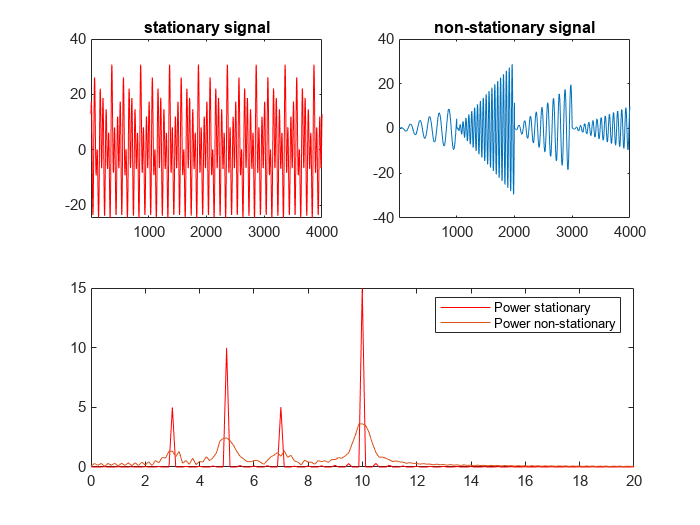

% list some frequencies
frex = [ 3 10 5 7 ];

% list some random amplitudes
amplit = [ 5 15 10 5 ];

% phases... 
phases = [  pi/7  pi/8  pi  pi/2 ];

% create a time series of sequenced sine waves
srate = 500;
time = -1:1/srate:1;
stationary  = zeros(1,length(time)*length(frex));
nonstationary = zeros(1,length(time)*length(frex));

for fi=1:length(frex)
    
    % compute sine wave
    temp_sine_wave = amplit(fi) * sin(2*pi*frex(fi).*time + phases(fi));
    
    % enter into stationary time series
    stationary = stationary + repmat(temp_sine_wave,1,length(frex));
    
    % optional change of amplitude over time
    temp_sine_wave = temp_sine_wave.*(time+1);
    
    % determine start and stop indices for insertion of sine wave
    start_idx = (fi-1)*length(time)+1;
    stop_idx  = (fi-1)*length(time)+length(time);
    
    % enter into non-stationary time series
    nonstationary(start_idx:stop_idx) = temp_sine_wave;
end

figure

% plot stationary signal
subplot(221)
plot(stationary,'r')
set(gca,'xlim',[1 length(stationary)])
title('stationary signal')

% plot non-stationary signal
subplot(222)
plot(nonstationary)

set(gca,'xlim',[1 length(nonstationary)])
title('non-stationary signal')

% perform FFT and plot
frequencies       = linspace(0,srate/2,length(nonstationary)/2+1);
fft_nonstationary = fft(nonstationary)/length(nonstationary);
fft_stationary    = fft(stationary)/length(stationary);
subplot(212)
plot(frequencies,abs(fft_stationary(1:length(frequencies)))*2,'r')
hold on
plot(frequencies,abs(fft_nonstationary(1:length(frequencies)))*2)
set(gca,'xlim',[0 max(frex)*2])
legend({'Power stationary';'Power non-stationary'})

### Exercise

- whats the maning of covariance non-statioanarity; write a code to show this, and explain the definition

- Generate a time series by creating and summing sine waves, as in figure 11.2B. Use between two and four sine waves, so that the individual sine waves are still somewhat visible in the sum. Perform a Fourier analysis (you can use the fft function) on the resulting time series and plot the power structure. Confirm that your code is correct by comparing the frequencies with nonzero power to the frequencies of the sine waves that you generated.

- Now try adding random noise to the signal before computing the Fourier transform. First, add a small amount of noise so that the sine waves are still visually recognizable. Next, add a large amount of noise so that the sine waves are no longer visually recognizable in the time domain data. Perform a Fourier analysis on the two noisy signals and plot the results. What is the effect of a small and a large amount of noise in the power spectrum? Are the sine waves with noise easier to detect in the time domain or in the frequency domain, or is it equally easy/difficult to detect a sine wave in the presence of noise?